# Model-Based Demo

Author: Artyom Voronin

Brno 2021

clc; clear all; close all; addpath("../utils/")

## Model Based approach using the Hammerstein-Wiener model

This approach use measured data to fit the Hammerstein-Wiener model. The model coefficients are used as features to develop a classification model.

### Import smaller dataensemble

path2data = fullfile('../data/data11/*.mat'); ext_files = ".mat";
datastore = fileEnsembleDatastore(path2data,ext_files);
datastore.ReadFcn = @readData;
datastore.WriteToMemberFcn = @writeData;
datastore.DataVariables = ["LeverPosition"; ...
                            "outValveHP"; ...
                            "outValveWP"];
datastore.ConditionVariables = ["Label"];
datastore.SelectedVariables = ["Label"; ...
                                "LeverPosition"; ...
                                "outValveHP"; ...
                                "outValveWP"];
clear path2data ext_files

### Extract signals

member = read(datastore);
u1 = member.outValveHP{1,1};
u2 = member.outValveWP{1,1};
u = u2.Data - u1.Data;
Ts = 1e-3;

calculate_features = 0;
if calculate_features
opt = oeOptions('Focus','simulation');
B_features = [];
F_features = [];
DC_features = [];
lab_features = [];

reset(datastore)
while hasdata(datastore)
    member = read(datastore);
    label = member.Label;
    x = member.LeverPosition{1,1}.Data;
    data = iddata(x, u, Ts);
    LinearModel = oe(data,[3 2 2],opt);
    mdl = nlhw(data, LinearModel, 'unitgain', 'saturation');
    B_features = [B_features; mdl.B{1,1}(3:end)];
    F_features = [F_features; mdl.F{1,1}];
    DC_features = [DC_features; dcgain(mdl)];
    lab_features = [lab_features; label]; 
    disp(string(progress(datastore)*100) + "% Done");
end
features_table = table(lab_features,DC_features,B_features(:,1),B_features(:,2),B_features(:,3),F_features(:,1),F_features(:,2),F_features(:,3), 'VariableNames', ["Label", "f1","f2","f3","f4","f5","f6","f7"])
else
    feature_table = load("features_table.mat").features_table
end

feature_table = 660×8 table
     Label        f1           f2            f3            f4        f5       f6          f7   
    ________    _______    __________    __________    __________    __    ________    ________

    "health"    0.30575      0.037273     -0.046688     0.0099372    1     -0.48497    -0.51333
    "health"    0.34656      0.054551    -0.0053757     -0.048624    1     -0.10396    -0.89445
    "health"      -1371      0.014093     -0.028052      0.013958    1       -1.999     0.99901
    "valve1"    0.35924      0.090554      -0.18022      0.089671    1      -1.9911     0.99111
    "valve1"     0.5059        0.1528      -0.30537       0.15258    1      -1.9981     0.99812
    "valve1"    0.40038    

### Conclusion

## Residual estimation using Simulation Model

### Import datastore and simulation model

addpath("../models/")
run("params.m");

fault_code = "1100001"

Healthy system behavior 


disp('[INFO] Parameters were loaded');

[INFO] Parameters were loaded


datastore = import_dataensemble("../data/data11/*.mat");
clear path2data ext_files
savepath = "../data/data_residual/";
member = read(datastore);
u1 = member.outValveHP{1,1};
u2 = member.outValveWP{1,1};
t = seconds(u1.Time);
u1 = u1.Data;
u2 = u2.Data;


### Reference result from Simulation Model

simOut = sim("../models/model_equation_simply_valves.slx");

position_ref = sim_signal_extract(get(logsout, "LeverPosition").Values);

Unrecognized function or variable 'logsout'.

velocity_ref = sim_signal_extract(get(logsout, "LeverVelocity").Values);
flow_ex_ref  = sim_signal_extract(get(logsout, "FlowExtrusion").Values);
flow_con_ref = sim_signal_extract(get(logsout, "FlowContraction").Values);

reference.position = position_ref;
reference.velocity = velocity_ref;
reference.flow_ex = flow_ex_ref;
reference.flow_con = flow_con_ref;     


### Example calculation for one member from dataset

[r_pos_t, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t);
data = table(label, {r_pos_tt}, {r_vel_tt}, {r_fe_tt}, {r_fc_tt}, 'VariableNames', ["Label", "LeverPosition_res", "LeverVelocity_res", "FlowExtrusion_res", "FlowContraction_res"])
save_data(savepath, data, 1)

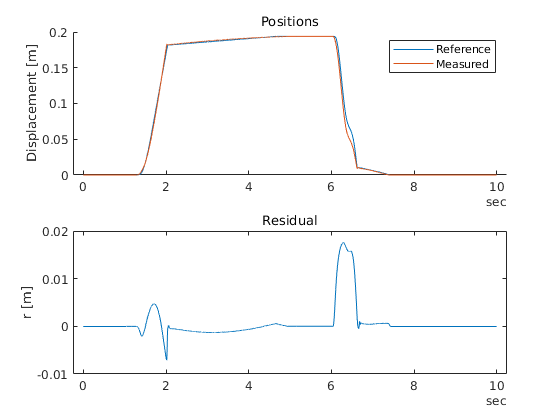

figure
subplot(2,1,1)
hold on
plot(position.Time, position_ref)
plot(position.Time, position.Data)
subtitle("Positions")
ylabel("Displacement [m]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(position.Time, r_pos)
ylabel("r [m]")
subtitle("Residual")

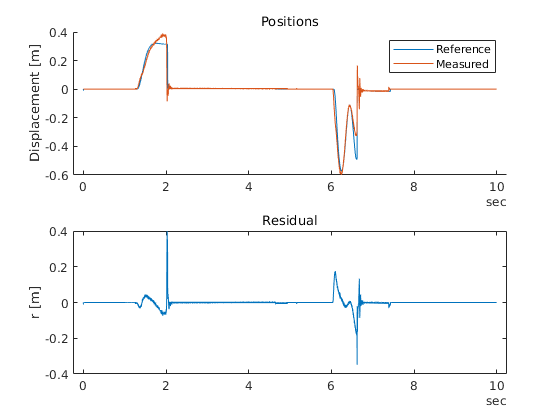

figure
subplot(2,1,1)
hold on
plot(velocity.Time, velocity_ref)
plot(position.Time, velocity.Data)
subtitle("Positions")
ylabel("Displacement [m]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(velocity.Time, r_vel)
ylabel("r [m]")
subtitle("Residual")

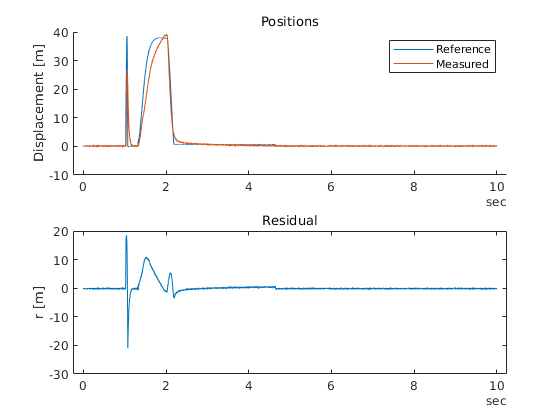


figure
subplot(2,1,1)
hold on
plot(flow_ex.Time, flow_ex_ref)
plot(flow_ex.Time, flow_ex.Data)
subtitle("Positions")
ylabel("Displacement [m]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(flow_ex.Time, r_fe)
ylabel("r [m]")
subtitle("Residual")

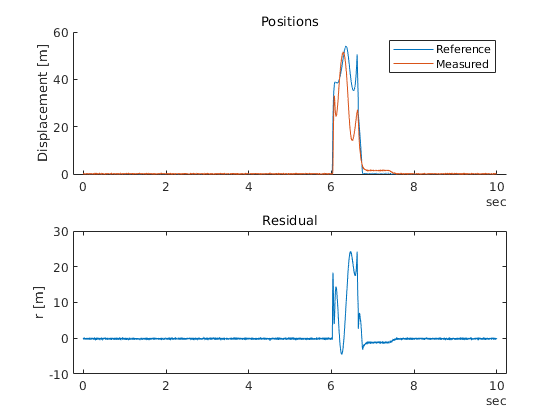


figure
subplot(2,1,1)
hold on
plot(flow_con.Time, flow_con_ref)
plot(flow_con.Time, flow_con.Data)
subtitle("Positions")
ylabel("Displacement [m]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(flow_con.Time, r_fc)
ylabel("r [m]")
subtitle("Residual")

### Calculate whole dataset

reset(datastore)
i = 0;
while hasdata(datastore)
    member = read(datastore);
    [label, r_pos_t, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t);
    data = table({label}, {r_pos_tt}, {r_vel_tt}, {r_fe_tt}, {r_fc_tt}, 'VariableNames', {'Label', 'LeverPosition_res', 'LeverVelocity_res', 'FlowExtrusion_res', 'FlowContraction_res'});
    save_data(savepath, data, i)
    disp(string(progress(datastore)*100) + "% Done");
    i = i + 1;
end

0.15152% Done
0.30303% Done
0.45455% Done
0.60606% Done
0.75758% Done
0.90909% Done
1.0606% Done
1.2121% Done
1.3636% Done
1.5152% Done
1.6667% Done
1.8182% Done
1.9697% Done
2.1212% Done
2.2727% Done
2.4242% Done
2.5758% Done
2.7273% Done
2.8788% Done
3.0303% Done
3.1818% Done
3.3333% Done
3.4848% Done
3.6364% Done
3.7879% Done
3.9394% Done
4.0909% Done
4.2424% Done
4.3939% Done
4.5455% Done
4.697% Done
4.8485% Done
5% Done
5.1515% Done
5.303% Done
5.4545% Done
5.6061% Done
5.7576% Done
5.9091% Done
6.0606% Done
6.2121% Done
6.3636% Done
6.5152% Done
6.6667% Done
6.8182% Done
6.9697% Done
7.1212% Done
7.2727% Done
7.4242% Done
7.5758% Done
7.7273% Done
7.8788% Done
8.0303% Done
8.1818% Done
8.3333% Done
8.4848% Done
8.6364% Done
8.7879% Done
8.9394% Done
9.0909% Done
9.2424% Done
9.3939% Done
9.5455% Done
9.697% Done
9.8485% Done
10% Done
10.1515% Done
10.303% Done
10.4545% Done
10.6061% Done
10.7576% Done
10.9091% Done
11.0606% Done
11.2121% Done
11.3636% Done
11.5152% Done
11.6667% 

### Import new datastore with residual signals

clear all
path2data = fullfile("../data/data_residual/*.mat"); ext_files = ".mat";
res_datastore = fileEnsembleDatastore(path2data,ext_files);

Error using matlab.io.datastore.DsFileSet (line 180)
Cannot find files or folders matching: '../data/data_residual/*.mat'.

Error in predmaint.internal.pmdata.PMFileDatastore (li

res_datastore.ReadFcn = @readData;
res_datastore.WriteToMemberFcn = @writeData;
res_datastore.DataVariables = ["LeverPosition_res"; ...
                            "LeverVelocity_res"; ...
                            "FlowExtrusion_res"; ...
                            "FlowContraction_res"];
res_datastore.ConditionVariables = ["Label"];
res_datastore.SelectedVariables = ["Label"; ...
                                "LeverPosition_res"; ...
                                "LeverVelocity_res"; ...
                                "FlowExtrusion_res"; ...
                                "FlowContraction_res"];
clear path2data ext_files
res_datastore       

## Generation Prognostic data from model

Generate response data from the model. In further steps this dataset can be imported as data ensemble format.

addpath("../models/")
run("params.m");
disp('[INFO] Parameters were loaded');
%%
output_path = '../data/data_gen_mdl_air_leak';
model = 'model_equation_simply_valves';

generate_data = 0;

if generate_data
air_leak = 1;
load_system(model);
open_system(model);
%open_system([model '/Mechanical system']);
runParallel = 0;
processParallel = 0;

% Run using Parallel Computing Toolbox
if runParallel && isempty(gcp('nocreate'))
    parpool([2,6]);
end

% Parameters changing in the time. For system behavior simulation purposes.
no_impact = linspace(1e-10, 1e-9, 10);
low_impact = linspace(1e-9, 1e-8, 10);
impact = linspace(1e-8, 1e-7, 20);
big_impact = linspace(1e-7, 1e-6, 30);

C_leak_values = [no_impact low_impact impact big_impact];


for i = 1:numel(C_leak_values)
    tmp = Simulink.SimulationInput(model);
    tmp = setVariable(tmp, 'C_leak', C_leak_values(i));
    tmp = setVariable(tmp, 'cycle', i);
    simin(i) = tmp;
end

if ~exist(fullfile(pwd, output_path), 'dir')
    mkdir(fullfile(pwd, output_path))
end

[status,e] = generateSimulationEnsemble(simin, ...
    fullfile(pwd, output_path), 'UseParallel', runParallel);
end


if status
    disp("[INFO] Data was successfully generated")
else
    warning("Fault in data generation")
end

clear all;
output_path = '../data/data_gen_mdl_air_leak';
ensemble = simulationEnsembleDatastore(output_path);
ensemble.SelectedVariables = ["FlowContraction"; "Cycle"];

figure
hold on
reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    x_data = data.FlowContraction{1,1};
    plot(x_data.Time, x_data.Data)
end
hold off
title("Displacement data")


Generated data

reset(ensemble)
ensemble.SelectedVariables = ["FlowContraction"; "Label"];

function ensemble = add_lable(ensemble)
% Append data
ensemble.DataVariables = [ensemble.DataVariables; "Label"];
% writeToLastMemberRead(ensemble, 'NewVariable', data);

reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    cycle = data.Cycle{1,1}.Data;
    writeToLastMemberRead(ensemble, "Label", cycle);
end
end

function signal = sim_signal_extract(signal)
    name = signal.Name;
    signal = ts2timetable(signal).(string(name))(1:end-1);
end

function [] = save_data(path, data, i)
    filename = path + "data_" + string(i) + ".mat";
    save(filename, "data")
end

function [label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t)
    Ts = 1e-3;
    label = member.Label{1,1};
    position = member.LeverPosition{1,1};
    velocity = position; velocity.Data = [diff(position.Data)/Ts; 0];
    flow_ex = member.FlowExtrusion{1,1};
    flow_con = member.FlowContraction{1,1};
    
    r_pos = reference.position-position.Data;
    r_vel = reference.velocity-velocity.Data;
    r_fe = reference.flow_ex-flow_ex.Data;
    r_fc = reference.flow_con-flow_con.Data;
    
    r_pos_tt = timetable(seconds(t), r_pos);
    r_vel_tt = timetable(seconds(t), r_vel);
    r_fe_tt = timetable(seconds(t), r_fe);
    r_fc_tt = timetable(seconds(t), r_fc);
end